# Inne algorytmy

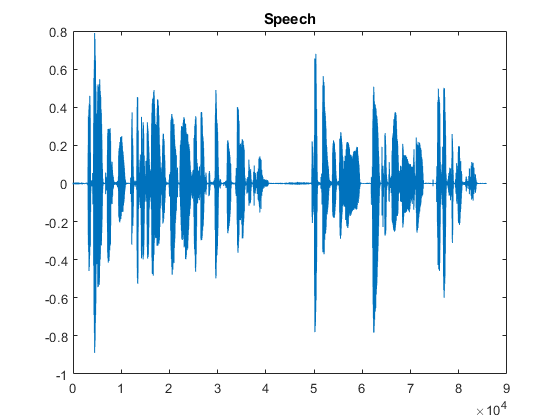

% lab14_ex_speech_compress.m
% Speech compression using linear prediction coding
clear all; close all;
ifigs = 1;             %  0/1 - to show figures inside the processing loop? 

% Parameters
Mlen=240;              % length of analyzed block of samples
Mstep=180;             % offset between analyzed data blocks (in samples)
Np=2;                  % prediction order (IIR-AR filter order)
where=181;             % initial position of the first voiced excitation
roffset=20;            % offset in auto-correlation function when find max
compress=[];           % table for calculated speech model coefficients
s=[];                  % the whole synthesized speech
ss=[];                 % one fragment of synthesized speech

% Read signal to compress
[x,fs]=audioread('mowa1.wav');	   % read speech signal (audio/wav/read)
figure; plot(x); title('Speech');  % display it

%soundsc(x,fs);% pause               % play it on loudspeakers (headphones)
N=length(x);                       % signal length
bs=zeros(1,Np);			   % synthesis filter buffer
Nblocks=floor((N-Mlen)/Mstep+1);   % number of speech blocks to be analyzed


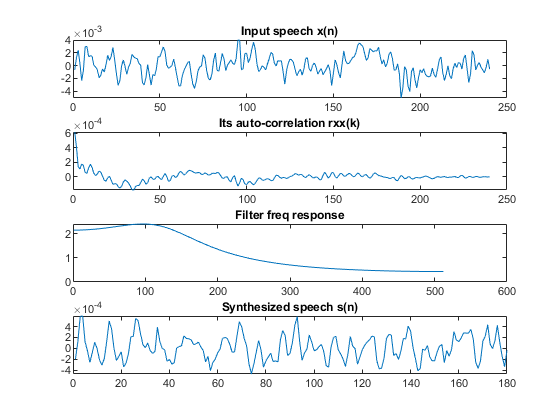

% MAIN PROCESSING LOOP
for  nr = 1 : Nblocks
   % take new data block (fragment of speech samples)
     n = 1+(nr-1)*Mstep : Mlen + (nr-1)*Mstep;
     bx = x(n);
   % ANALYSIS - calculate speech model parameters
	 bx = bx - mean(bx);                             % remove mean value
     for k = 0 : Mlen-1
         r(k+1)=sum( bx(1:Mlen-k) .* bx(1+k:Mlen) ); % calculate auto-correlation
     end                                             % try: r=xcorr(x,'unbiased')
     if(ifigs==1)
       subplot(411); plot(n,bx); title('Input speech x(n)');
       subplot(412); plot(r); title('Its auto-correlation rxx(k)');
     end
     [rmax,imax] = max( r(roffset : Mlen)  );        % find max of auto-correlation
     imax = imax+(roffset-1);                        % its argument (position)
     
     if ( rmax > 0.35*r(1) )  T=imax; else T=0; end  % is the speech periodic?
     
     if (T>80) T=round(T/2); end                     % second sub-harmonic found
     T; % pause                                      % display speech period T
     
     % my part 
     a = BubLevAlf(r, 2);
     a = a(2:end);
     
     % find coeffs of LPC filter
     gain=r(1)+r(2:Np+1)*a;                      % find filter gain
     H=freqz(1,[1;a]);                           % find filter frequency response
     if(ifigs==1) subplot(413); plot(abs(H)); title('Filter freq response'); end
     compress=[compress; T; gain; a; ];          % store parameter values

   % SYNTHESIS - generate speech using calculated parameters
     %T = 80; % remove "%" and set: T = 80, 50, 30, 0
     if (T~=0) where=where-Mstep; end            % next excitation=1 position
     for n=1:Mstep                               % SYNTHESIS LOOP START
         if( T==0)                               %
           % exc=2*(rand(1,1)-0.5); where=271;   % random excitation
             exc=0.5*randn(1,1); where=271;      % random excitation
         else                                    %
            if (n==where) exc=1; where=where+T;  % excitation = 1
            else exc=0; end                      % excitation = 0
         end                                     %
         ss(n) = gain*exc - bs*a;                % filtering excitation
         bs = [ss(n) bs(1:Np-1) ];               % shifting the output buffer
     end                                         % SYNTHESIS LOOP END
     
     s = [s ss];                                 % store the synthesized speech
     if(ifigs==1) subplot(414); plot(ss); title('Synthesized speech s(n)'); end
     s;
end


% Finished!
figure; plot(s); title('Synthesized speech');
% soundsc(s,fs)

function a = BubLevAlf(r, m)

    r0 = r(1); r = r(2:end);
    a = zeros(m+1, 1);
    a(1) = 1;
    E = r0;
    a(2) = -r(1)/r0;
    k(1) = a(2);
    q = r(1);
    
    for i=1:m-1
        E=E+(q*k(i));
        q=r(i+1);
        q = q + sum(r(1:i) .* a(i+1:-1:2), 'all');
        k(i+1)= -q/E;
        tmp(1:i) = k(i+1) .* a(i+1:-1:2);
        a(2:i+1) = a(2:i+1) + tmp(1:i)';
        a(i+2) = k(i+1);
    end
end

function a = DurbinLevinsonAlgHandler(r)
    a = DurbinLevinsonAlg(r(2:end),1,[],r(1));
end
    
function a = DurbinLevinsonAlg(r, i, a, E)
    if i==length(r)
        a;
        return
    end
    
    gamm = 0;
    for it=1:i
        elem = r(it);
        if it~=i
            elem = elem * a(i-1,it);
        end
        gamm = gamm + elem;
    end
    gamm = gamm/E;
    a(i,i)= -gamm;
    
    if i > 0
        for j=1:i-1
            a(i,j)=a(i-1,j)-gamm*a(i-1,i-j);
        end
    end
    
    a = DurbinLevinsonAlg(r,i+1,a,(1-pow2(gamm))*E);
end